# Optimal Estimation - Homework 2

### Tanner Koza

## Problem 1

Two random variables $x_1$ and $x_2$ have a joint PDF that is uniform inside the circle (in the $x_1$-$x_2$ plane) with radius 2, and zero outside the circle.

### Find: 

- **Part A: **Find the math expression of the joint PDF function.

- **Part B: **Find the conditional PDF $P_{x_1|x_2}(x_2|x_1=0.5)$.

- **Part C: **Are the two random variables uncorrelated?

- **Part D: **Are the two random variables statistically independent? Hint: find $p_{x_1}(x_1)$ and $p_{x_2}(x_2)$ and check if $p_{x_1x_2}(x_1,x_2)=p_{x_1}(x_1)p_{x_2}(x_2)$.

### Solution: 

- **Part A: **Considering the joint PDF of these two random variables is uniform inside of a circle, the probabilities of the PDF are represented by the height of a cylinder created by the circle. The volume of this circle should sum to 1, therefore, the height (probability) within the bounds of the circle is $h = \frac{1}{\pi r^2}$, where $r$ is 2. This probabilty makes up half of the piecewise that defines the whole joint PDF below:


$$f_{x_1x_2}(x_1,x_2) = \left\{
        \begin{array}{ll}
            \frac{1}{4\pi} & \quad \sqrt{x_1^2 + x_2^2}  \le 2 \\
            0 & \quad else 

        \end{array}
    \right.$$


- **Part B: **The conditional PDF can be found using the following:


$$P_{x_1|x_2}(x_2|x_1=0.5) = \frac{f_{x_1x_2}}{f_{x_1}}$$


$f_{x_1x_2}$ is defined within the circle in Part A and $f_{x_1}$ is defined as follows:


$$f_{x_1}=\int f_{x_1x_2}(x_1,x_2)dx_2$$


where the bounds across $x_2$ are given by the condition of $x_1 = 0.5$ below:


$$\sqrt{(0.5)^2+x_2^2}\le2
$$



$$0.25+x_2^2\le4$$



$$x_2^2\le3.75$$



$$x_2 = \pm \sqrt{3.75$$


Using these bounds, $f_{x_1}$ is:


$$f_{x_1} = \int_{-\sqrt{3.75}}^{\sqrt{3.75}}\frac{1}{4\pi}dx_2$$



$$\left. = \frac{x_2}{4 \pi} \right|^{\sqrt{3.75}}_{-\sqrt{3.75}$$



$$\left. = \frac{2\sqrt{3.75}}{4\pi}$$


Finally, evaluating the conditional probability yields:


$$P_{x_1|x_2}(x_2|x_1=0.5) = \frac{1}{4\pi}(\frac{4\pi}{2\sqrt{3.75}})=\frac{1}{2\sqrt{3.75}}$$


- **Part C: **The two random variables are uncorrelated and can be proven with the following uncorrelated property:


$$E[x_1x_2]-E[x_1]E[x_2] =0
$$


where $E[x_1]$ and $E[x_2]$ are $0$ as all possible values for each are uniformly centered around $0$. This was assumed based on the prompt stating the joint PDF is a circle. $E[x_1x_2]$ is evaluated as the following:


$$E[x_1x_2] = \int \int x_1x_2 f_{x_1x_2}(x_1,x_2)dx_1dx_2$$



$$= \int \int x_1 x_2 (\frac{1}{4\pi})dx_1dx_2$$


where the bounds across each random variable are given by the following:


$$\pm\sqrt{4-x_1^2}$$



$$\pm\sqrt{4-x_2^2}$$


Therefore, $E[x_1x_2]$ is:


$$E[x_1x_2] = \frac{1}{4\pi}\int_{-\sqrt{4-x_1^2}}^{\sqrt{4-x_1^2}} x_2 \left. (\frac{x_1^2}{2}) \right|^{\sqrt{4-x_2^2}}_{-\sqrt{4-x_2^2}} = 0$$


Because of the following:


$$\left. (\frac{x_1^2}{2}) \right|^{\sqrt{4-x_2^2}}_{-\sqrt{4-x_2^2}} = 0$$


Therefore:


$$E[x_1x_2]-E[x_1]E[x_2] =0 - (0)(0) = 0$$


meaning the two random variables are uncorrelated.

- **Part D: **The two random variables are statistically dependent and can be proven with the following independence property:


$$f_{x_1x_2} = f_{x_1}f_{x_2}$$


The PDFs for $x_1$ and $x_2$ can be found using the same method in Part B with the general bounds used in Part C. $f_{x_1}$ is the following:


$$f_{x_1} = \int_{-\sqrt{4-x_1^2}}^{\sqrt{4-x_1^2}}\frac{1}{4\pi}dx_2$$



$$\left. = \frac{x_2}{4 \pi} \right|^{\sqrt{4-x_1^2}}_{-\sqrt{4-x_1^2}$$



$$\left. = \frac{2\sqrt{4-x_1^2}}{4\pi}$$


$f_{x_2}$ is the following:


$$f_{x_2} = \int_{-\sqrt{4-x_2^2}}^{\sqrt{4-x_2^2}}\frac{1}{4\pi}dx_1$$



$$\left. = \frac{x_1}{4 \pi} \right|^{\sqrt{4-x_2^2}}_{-\sqrt{4-x_2^2}$$



$$\left. = \frac{2\sqrt{4-x_2^2}}{4\pi}$$


Evaluating the independence property, it can be seen the joint PDF and multiplied PDF are not equal. Therefore, $x_1$ and $x_2$ are statistically dependent.


$$\frac{1}{4\pi} \neq (\frac{2\sqrt{4-x_1^2}}{4\pi})(\frac{2\sqrt{4-x_2^2}}{4\pi})$$


## Problem 2

The stationary process $x(t)$ has an autocorrelation function of the form:


$$R_x(\tau) = \sigma^2e^{-\beta |\tau|}$$


Another process $y(t)$ is related to $x(t)$ by the deterministic equation:


$$y(t) = ax(t) + b$$


where the constants $a$ and $b$ are known.

### **Find:**

- **Part A: **What is the autocorrelation function for $y(t)$?

- **Part B: **What is the crosscorrelation function $R_{xy}(\tau) = E[x(t)y(t+\tau)]$?

### Solution:

- **Part A: ** The following is the solution for the autocorrelation of $y(t)$:


$$R_y(t_1, t_2) = E[y(t_1)y(t_2)]$$



$$= E[(ax(t_1)+b)(ax(t_2)+b)]$$



$$= E[a^2x(t_1)x(t_2) + abx(t_1) + abx(t_2) + b^2]$$



$$= a^2E[x(t_1)x(t_2)] + abE[x(t_1)] + abE[x(t_2)] + b^2$$


Considering:


$$E[x(t_1)] = E[x(t_2)] = \bar{x}$$


and


$$E[x(t_1)x(t_2)] = \sigma^2e^{-\beta |\tau|}$$



$$R_y(t_1,t_2) = a^2\sigma^2e^{-\beta |\tau|} + 2ab\bar{x}+ b^2$$


This can be reduced further given the property $R(\tau = 0) = \sigma^2 +  \bar{x^} ^2$. Knowing $R_x(0) = \sigma^2 e^{-\beta|0|} = \sigma^2$, then $\bar{x}$ is known to be 0. This means the autocorrelation of $y(t)$ is:


$$R_y(t_1,t_2) = a^2\sigma^2e^{-\beta |\tau|}+ b^2$$


- **Part B: **The following is the solution for the crosscorrelation function for $x(t)$ and $y(t)$:


$$R_{xy}(\tau) = E[x(t)y(t+\tau)] = E[x(t_1)(ax(t_2)+b)]$$



$$= E[ax(t_1)x(t_2) + bx(t_1)]$$



$$=aE[x(t_1)x(t_2)] + bE[x(t_1)]$$



$$= a\sigma^2e^{-\beta |\tau|} + b\bar{x}$$



$$= a\sigma^2e^{-\beta |\tau|}$$


## Problem 3

Use least squares to identify a gyroscopes scale factor $(a)$ and bias $(b)$. Simulate the gyroscope using:


$$g(k) = ar(k) + b + n(k)$$



$$n\tilde{}N(0,\sigma = 0.3 degs/s)$$



$$r(k) = 100sin(\omega t)$$


### Find:

- **Part A: **Perform the least squares with 10 samples.

- **Part B: **Repeat Part A 1000 times and calculates the mean and standard deviation of the estimate errors. Compare the results to the theoretically expected mean and standard deviation.

- **Part C: **Repeat Parts A & B using 1000 samples. What does the theoretical and Monte-Carlo standard deviation of the estimated errors approach?

- **Part D: **Set up the problem to run as a recursive least squares and plot the coefficients and theoretical standard deviation of the estimate error and the actual estimate error as a function of time.

### Solution:

- **Part A & B: ** A scale factor of 3 and a bias of 10 were selected for $a$ and $b$ to be estimated. The following code shows the batched least squares estimation. The resulting plots show the  

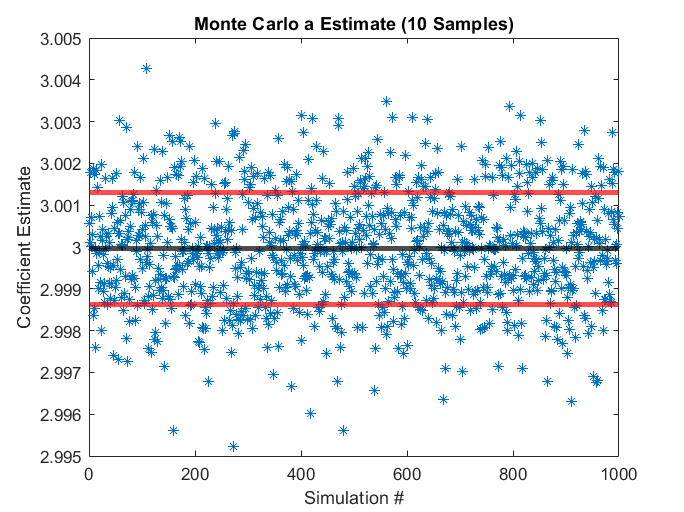

%% Parts A & B

% Time Initialization
dt = 0.1;
t_end = 30;
t = 0:dt:t_end;
numSamps = length(t);

% Monte Carlo Initialization
numSims = 1000;

% Noise & Frequency Initialization
sigma = 0.3; % deg/s
var = sigma^2;
freq = 2;
omega = freq * (2 * pi) ; % rads/s

% Arbitrary Coefficient Initialization
a = 3;
b = 10;

% Least Squares Initialization
estSamps = 10; % # of samples used in estimate
R = var * eye(estSamps);

% Preallocation
r = zeros(numSamps,1); 
g = zeros(numSamps,1);
est = zeros(numSims,2);


for i = 1:numSims

    n = sigma * randn(numSamps,1);

    for k = 1:numSamps
       
        r(k) = 100 * sin(omega * t(k));
    
        g(k) = a * r(k) + b + n(k); % degs/s
    
    end

H = [r(1:estSamps) ones(estSamps,1)];
est(i,:) = (H' * H)^-1 * H' * g(1:estSamps);

P = (H' * R^-1 * H)^-1 ;
end

mean_est = mean(est);
std_est = std(est); % Monte Carlo Standard Deviation

std_a = sqrt(P(1,1)); % Theoretical Standard Deviation
std_b = sqrt(P(2,2));

figure
plot(1:numSims, est(:,1), '*')
hold on
yline(mean_est(1),'k','LineWidth',3)
yline(mean_est(1) + std_est(1),'r','LineWidth',3)
yline(mean_est(1) - std_est(1),'r','LineWidth',3)
title('Monte Carlo a Estimate (10 Samples)')
xlabel('Simulation #')
ylabel('Coefficient Estimate')

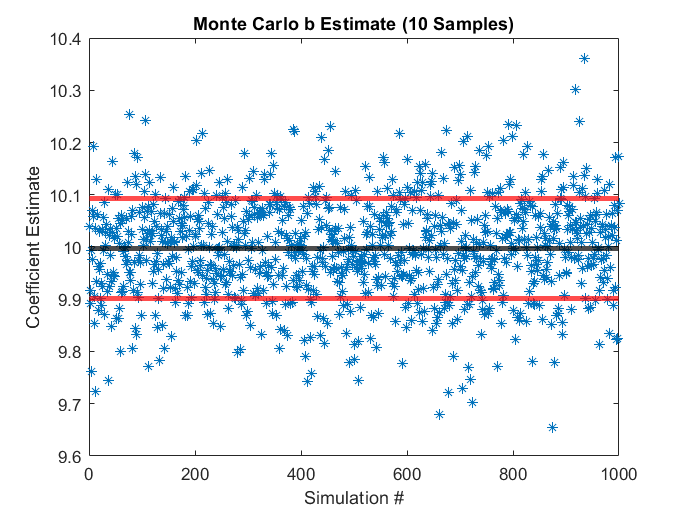


figure
plot(1:numSims, est(:,2), '*')
hold on
yline(mean_est(2),'k','LineWidth',3)
yline(mean_est(2) + std_est(2),'r','LineWidth',3)
yline(mean_est(2) - std_est(2),'r','LineWidth',3)
title('Monte Carlo b Estimate (10 Samples)')
xlabel('Simulation #')
ylabel('Coefficient Estimate')


clearvars



- **Part B:**

- **Part C:**

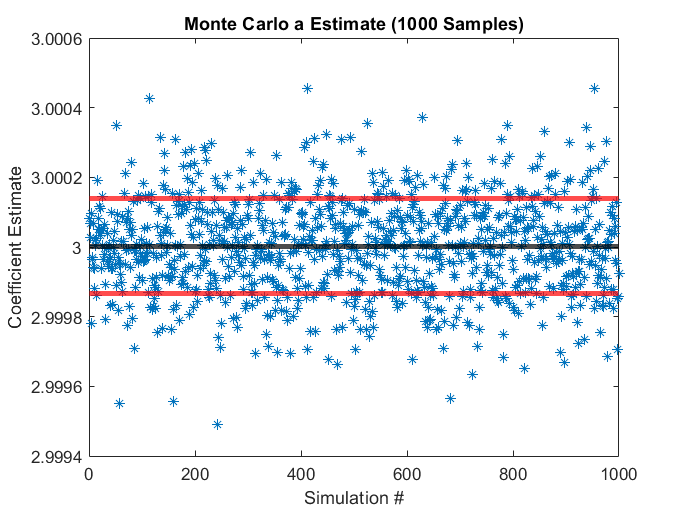

%% Part C

% Time Initialization
dt = 0.1;
t_end = 300;
t = 0:dt:t_end;
numSamps = length(t);

% Monte Carlo Initialization
numSims = 1000;

% Noise & Frequency Initialization
sigma = 0.3; % deg/s
var = sigma^2;
freq = 2;
omega = freq * (2 * pi) ; % rads/s

% Arbitrary Coefficient Initialization
a = 3;
b = 10;

% Least Squares Initialization
estSamps = 1000; % # of samples used in estimate
R = var * eye(estSamps);

% Preallocation
r = zeros(numSamps,1); 
g = zeros(numSamps,1);
est = zeros(numSims,2);


for i = 1:numSims

    n = sigma * randn(numSamps,1);

    for k = 1:numSamps
       
        r(k) = 100 * sin(omega * t(k));
    
        g(k) = a * r(k) + b + n(k); % degs/s
    
    end

H = [r(1:estSamps) ones(estSamps,1)];
est(i,:) = (H' * H)^-1 * H' * g(1:estSamps);

P = (H' * R^-1 * H)^-1 ;
end

mean_est = mean(est);
std_est = std(est); % Monte Carlo Standard Deviation

std_a = sqrt(P(1,1)); % Theoretical Standard Deviation
std_b = sqrt(P(2,2));

figure
plot(1:numSims, est(:,1), '*')
hold on
yline(mean_est(1),'k','LineWidth',3)
yline(mean_est(1) + std_est(1),'r','LineWidth',3)
yline(mean_est(1) - std_est(1),'r','LineWidth',3)
title('Monte Carlo a Estimate (1000 Samples)')
xlabel('Simulation #')
ylabel('Coefficient Estimate')

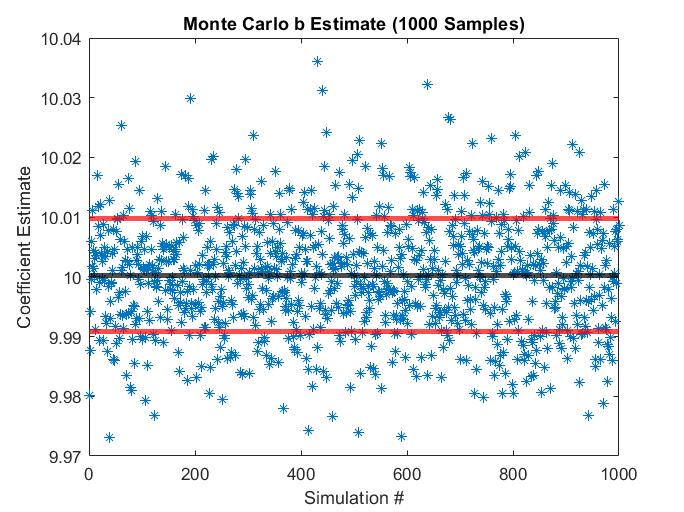


figure
plot(1:numSims, est(:,2), '*')
hold on
yline(mean_est(2),'k','LineWidth',3)
yline(mean_est(2) + std_est(2),'r','LineWidth',3)
yline(mean_est(2) - std_est(2),'r','LineWidth',3)
title('Monte Carlo b Estimate (1000 Samples)')
xlabel('Simulation #')
ylabel('Coefficient Estimate')


clearvars

- **Part D:**

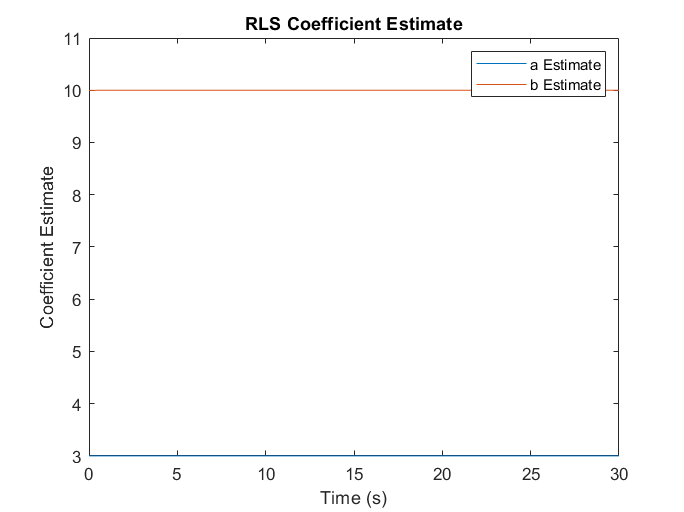

%% Part D

% Time Initialization
dt = 0.1;
t_end = 30; % s
t = 0:dt:t_end;
numSamps = length(t);

% Monte Carlo Initialization
numSims = 1000;

% Noise & Frequency Initialization
sigma = 0.3; % deg/s
var = sigma^2;
freq = 2;
omega = freq * (2 * pi) ; % rads/s

% Arbitrary Coefficient Initialization
a = 3;
b = 10;

% Recursive Least Squares Initialization
est = zeros(2,1);
R = var;
P = eye(2);

% Preallocation
est_a = zeros(numSamps,numSims);
est_b = zeros(numSamps,numSims);
std_a = zeros(numSamps,numSims);
std_b = zeros(numSamps,numSims);


for i = 1:numSims

    n = sigma * randn(numSamps,1);
    r = 100 * sin(omega .* t);
    g = a * r' + b + n;

    for j = 1:numSamps

        H = [r(j) 1];

        K = P * H' * (H * P * H' + R)^ -1;

        est =  est + K * (g(j) - H * est);

        est_a(j,i) = est(1);
        est_b(j,i) = est(2);

        P = (P^-1 + H' * R^-1 * H)^ -1;

        std_a(j,i) = sqrt(P(1,1));
        std_b(j,i) = sqrt(P(2,2)); 

    end

end

mean_est_a = mean(est_a,2);
mean_est_b = mean(est_b,2);

th_std_a = mean(std_a,2);
th_std_b = mean(std_b,2);

mc_std_a = std(est_a,0,2);
mc_std_b = std(est_b,0,2);

figure
plot(t,mean_est_a)
hold on
plot(t,mean_est_b)
title('RLS Coefficient Estimate')
xlabel('Time (s)')
ylabel('Coefficient Estimate')
legend('a Estimate','b Estimate')
ylim([-inf 11])

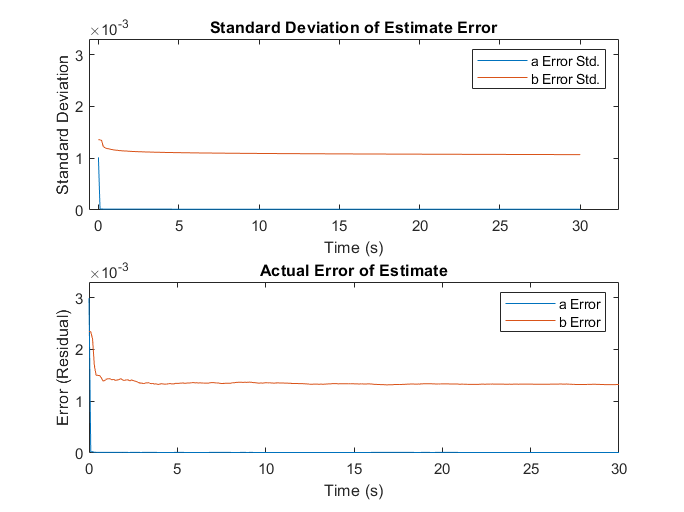


figure
ax(1) = subplot(2,1,1);
plot(t,th_std_a, 'Parent', ax(1))
hold on
plot(t,th_std_b, 'Parent', ax(1))
title('Standard Deviation of Estimate Error')
xlabel('Time (s)')
ylabel('Standard Deviation')
legend('a Error Std.','b Error Std.')

ax(2) = subplot(2,1,2);
plot(t,abs(a - mean_est_a),'Parent', ax(2))
hold on
plot(t,abs(b - mean_est_b), 'Parent', ax(2))
title('Actual Error of Estimate')
xlabel('Time (s)')
ylabel('Error (Residual)')
legend('a Error','b Error')

linkaxes(ax,'y');